# Robotics 2 20 06 5

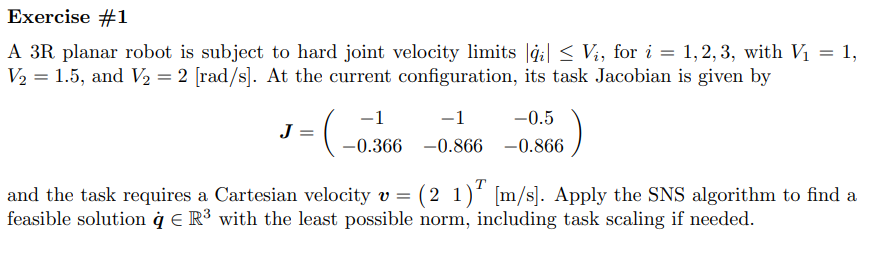

% clear all; clc;close all;
% V_=[2,1]'
% q_dMax_ = [1,1.5,2] % Maximum acceleration constraints of joints
% % 
% q_dMaxTemp_ = q_dMax_ % Maximum acceleration constraints of joints
% % V_=[0,10]'
% qnum = 3; %Number of joints
% q = sym('q', [1 qnum],'real');
% d = sym('d', [1 qnum],'real');
% a = sym('a', [1 qnum],'real');
% % 
% L = sym('l','real')
% L_=2
% % % a, alpha, 
% R3Robot = [L 0 0 q(1);
%            L 0 0 q(2);
% %            L 0 0 q(3);
%            L 0 0 q(3)]
% %        
% T0_EE = getTransformationMatrix(R3Robot)
% % 
% % % Calculate the Jacobian (Rotational)
% config = 'RRR';
% [Jp, Jo,Jps, Jos] = getJacobian(R3Robot,config)
% % %Jac = [Jp;Jo]
% % %Eliminate the zero rows, which represent the unused variables
% Jp = Jp(~all(Jp == 0,2),:)
% % 
% q_ = [pi/4,pi/4, pi/3]
% 
% % J_ = subs(Jp, [q L], [q_ L_])
% J_ =sym([-1 -1 -0.5;-0.366 -0.866 -0.866])
% % digits(5)
% % vpa(J_)
% rank_J_=rank(J_)
% rank_V_=rank(V_)
% if(rank_J_<2)
% disp("Range of J_ is lower than 2  IT IS NOT FULL RANK PAY ATTENTION!!")
% if(rank_J_==rank_V_)
% disp("but The rank is inside of rank V_ all are: "+rank_J_)
% disp("BUT CHECK IF V_ INSIDE OF THE RANGE OF R{j}, SEE THE FORM WHEN IT IS OR NOT CERO!!")
% end
% end

% 
% abs_on=true;
% autodetectsign=true
%  [qdotstarFinal] = SNSMethod1(V_,J_,q_dMax_',abs_on,autodetectsign)
% 
% [qdotstarFinal,W] = SNSMethod2(V_,J_,q_dMax_')%,Qdotmin,Qdotdmax)
% 
% vpa(qdotstarFinal)
% pd2_=vpa(J_)*qdotstarFinal
% vpa(norm(qdotstarFinal))

## 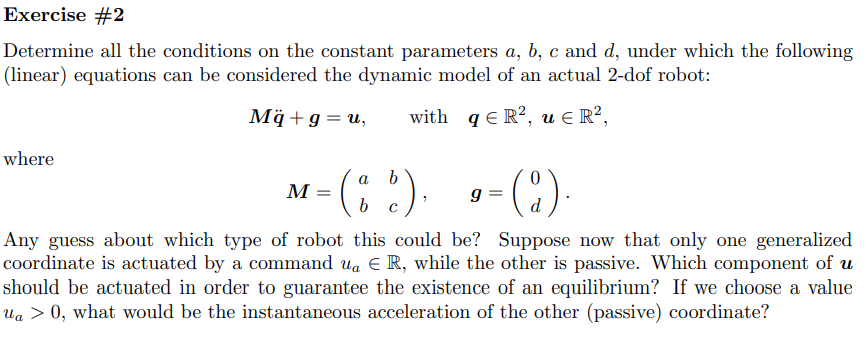

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,1];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

defining z struct

% R2Robot=['pp';'xx';sigma ]   ;    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real');
% % z.opt_expr={l,[l_0,l_0,l_0,l_0]'};%not necessary
% 
% % z.rcdefined=true;

## axis offset

% % 
% % % h=sym('h','real')
% % % %x,y,z
% % % z.xyx_offset=sym(zeros(3,n));
% % % z.xyx_offset(:,1)=[0,h,0]';%

% % %Global q reference?
% % % clear
% % % z.q_global
% % z.global_q_reference=false;
% % if(z.global_q_reference)
% %     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% % end
% % 

% % % R2Robot=['rr';'x~']       
% xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% z.angle_=[0,alpha_angle]
% % [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I,1,[],[],'alpha',false,angle_desired)
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,q,qd)
% 
% % [C,cac,Csubs] = getCs(Msubs,q',qd')
% 

% cac
% M

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% 

% u =simplify( M*qdd + cac+g_q)
% 

## linear parameterization part 1

%  [g_subs, dynamicParametersG, aG] = getDynamicParameters2(g_q,q,[],1)%l')

## part 2

% % % 
%  [Yg, Ygshort] = getLinearParametrization(g_subs,aG)


## exercise 3

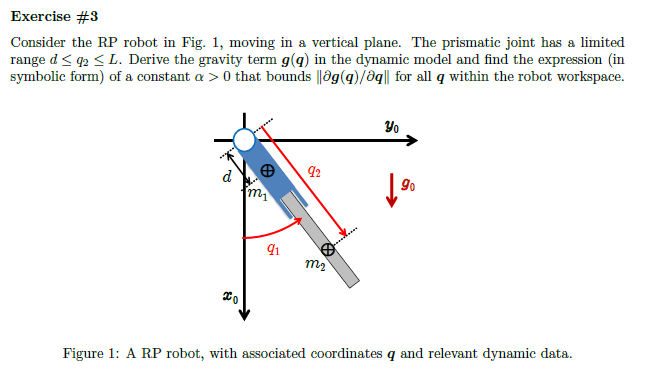

% % This part is isolated from previous section
% clear;clc;
% 
% syms k q1(t) q2(t) q3(t)
% sigma = [0,1];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real'); 
% 
% dc = sym('dc_', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';

s

% R2Robot=['rp';'xx';[1,1]]    
% z = Gen_param(n);
% z.sigmaD=R2Robot
% z.l=l
% z.q=q
% z.q_dot=qd
% z.dc=dc
% z.m=m
% z.I=I
% z.methodD=1
% z.dhTable=[]
% z.firstParam='alpha'
% z.rc=[]
% z.movingframes=[]
% z.angle_=sym(zeros(1,n))
% z.opt_expr={[l(1)+q(2)],[q(2)]}
% z.rcdefined=true;

% 
%    
% xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,q,qd)
% 
% % [C,cac,Csubs] = getCs(Msubs,q',qd')
% u =simplify( M*qdd + cac)

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)

% g_q

% 
% U{:}
% lambda_def=Get_A_matrix(g_q,q)
% toreplace=[cos(q(1)),sin(q(1)),q(2)]
% L=sym('L','real')
% toreplace_=[1,1,L]
% lambda1_=subs(lambda_def.lambda2_,toreplace,toreplace_)
% alpha_=sqrt(lambda1_(2))
% 


## Exercise 4

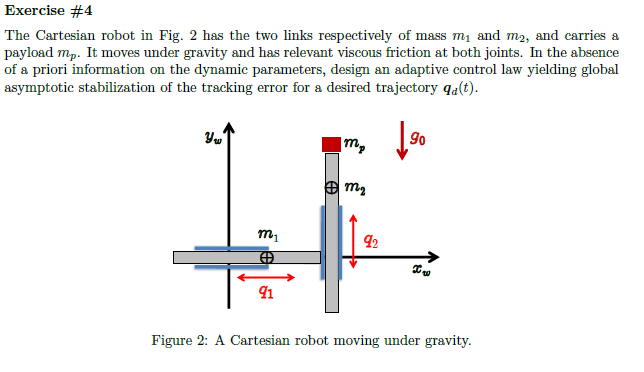

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [0,0];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q', [n 1],'real');
q_d= sym('q_d', [n 1],'real');
q_dot_d= sym('q_dot_d', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');

q_r = sym('q_r', [n 1],'real');
q_dot_r = sym('q_dot_r_', [n 1],'real');
q_ddot_r = sym('q_ddot_r_', [n 1],'real');

% 
dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
m(2)=m(2)+m_p

$$m = \left(\begin{array}{c} m_{1}\\ m_{2}+m_{p} \end{array}\right)$$

I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

s

R2Robot=['pp';'xy';[1,1]]    

R2Robot = 3×2 char array
    'pp'
    'xy'
    ''


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_dot_d=q_dot_d;
z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismoto

% z.dhTable=[]
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.opt_expr={[l(1)+q(2)],[q(2)]};
% z.rcdefined=true;


   
% xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% VarShortRobot.M
% angle_desired=[0,0]
% l(1)=0
[Pc,vc,w,T,Ti,M] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {l1 + q2  q2}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
            

si falla aquí está el error


anglerot = 1×1 cell array
    {4×4 sym}


method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)\,\left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right) \end{array}\right)$$

    "check the _ last term it is needed for the function for example q_1_ should be the right way to define a varaible to convert to time dependent"



$$Pc = \left(\begin{array}{cc} q_{1} & q_{1}\\ 0 & q_{2}\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} {\dot{q}}_{1} & {\dot{q}}_{1}\\ 0 & {\dot{q}}_{2}\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

$$T = \left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)\,\left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right)+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)\,\left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right) \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{1}+m_{2}+m_{p} & 0\\ 0 & m_{2}+m_{p} \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,q,q_dot);

>> Getting  the Christoffel’sym. Might take a while...


Viscouz terms

F_v=sym('F_v',[n,1],'real').*eye(n)

$$F\_v = \left(\begin{array}{cc} F_{\mathrm{v1}} & 0\\ 0 & F_{\mathrm{v2}} \end{array}\right)$$

isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = g_{0}\,q_{2}\,\left(m_{2}+m_{p}\right)$$

$$PE\_short = g_{0}\,q_{2}\,\left(m_{2}+m_{p}\right)$$

$$g\_q\_short = \left(\begin{array}{c} 0\\ g_{0}\,\left(m_{2}+m_{p}\right) \end{array}\right)$$

$$g\_q = \left(\begin{array}{c} 0\\ g_{0}\,\left(m_{2}+m_{p}\right) \end{array}\right)$$

$$PE = g_{0}\,q_{2}\,\left(m_{2}+m_{p}\right)$$

U = 1×2 cell array
    {[0]}    {[g0*q2*(m2 + m_p)]}


$$g\_q\_short = \left(\begin{array}{c} 0\\ g_{0}\,\left(m_{2}+m_{p}\right) \end{array}\right)$$

$$PE\_short = g_{0}\,q_{2}\,\left(m_{2}+m_{p}\right)$$

U{:}

$$ans = 0$$

$$ans = g_{0}\,q_{2}\,\left(m_{2}+m_{p}\right)$$

g_q

$$g\_q = \left(\begin{array}{c} 0\\ g_{0}\,\left(m_{2}+m_{p}\right) \end{array}\right)$$

## get dinamyc paramters

% [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,q,[])
% [Gsubs, dynamicParametersG, aG] = getDynamicParameters2(g_q,q,[g0],2)
[All, dynamicParamsReturn, a]= getDynamicParameters3([M,g_q,F_v],q,[q_dot.',g0],2)

>> Getting dynamic coefficients. Might take a while...


$$All = \left(\begin{array}{ccccc} a_{4} & 0 & 0 & a_{1} & 0\\ 0 & a_{3} & a_{3}\,g_{0} & 0 & a_{2} \end{array}\right)$$

$$dynamicParamsReturn = \left(\begin{array}{c} F_{\mathrm{v1}}\\ F_{\mathrm{v2}}\\ m_{2}+m_{p}\\ m_{1}+m_{2}+m_{p} \end{array}\right)$$

$$a = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4} \end{array}\right)$$


% [C,cac,Csubs] = getCs(Msubs,q',qd';)
u =simplify( M*q_ddot + cac+g_q+F_v*q_dot)

$$u = \left(\begin{array}{c} F_{\mathrm{v1}}\,{\dot{q}}_{1}+{\ddot{q}}_{1}\,\left(m_{1}+m_{2}+m_{p}\right)\\ g_{0}\,\left(m_{2}+m_{p}\right)+{\ddot{q}}_{2}\,\left(m_{2}+m_{p}\right)+F_{\mathrm{v2}}\,{\dot{q}}_{2} \end{array}\right)$$

[usubs, dynamicParametersu, au] = getDynamicParameters3(u,q,[q_ddot;q_dot],2)

>> Getting dynamic coefficients. Might take a while...


$$usubs = \left(\begin{array}{c} a_{1}\,{\dot{q}}_{1}+a_{5}\,{\ddot{q}}_{1}\\ a_{4}+a_{2}\,{\dot{q}}_{2}+a_{3}\,{\ddot{q}}_{2} \end{array}\right)$$

$$dynamicParametersu = \left(\begin{array}{c} F_{\mathrm{v1}}\\ F_{\mathrm{v2}}\\ m_{2}+m_{p}\\ g_{0}\,\left(m_{2}+m_{p}\right)\\ m_{1}+m_{2}+m_{p} \end{array}\right)$$

$$au = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5} \end{array}\right)$$


Msubs = All(:,1:n)

$$Msubs = \left(\begin{array}{cc} a_{4} & 0\\ 0 & a_{3} \end{array}\right)$$

gSubs = (All(:,n+1))

$$gSubs = \left(\begin{array}{c} 0\\ a_{3}\,g_{0} \end{array}\right)$$

FSubs = All(:,n+2:end)

$$FSubs = \left(\begin{array}{cc} a_{1} & 0\\ 0 & a_{2} \end{array}\right)$$

u_subs = Msubs*q_ddot_r + gSubs +FSubs*q_dot_r

$$u\_subs = \left(\begin{array}{c} a_{1}\,{\dot{q}}_{r,1}+a_{4}\,{\ddot{q}}_{r,1}\\ a_{3}\,g_{0}+a_{2}\,{\dot{q}}_{r,2}+a_{3}\,{\ddot{q}}_{r,2} \end{array}\right)$$

## Linearization

Y=sym('Y','real')

$$Y = Y$$

Y_=getLinearParametrization(u_subs,a)

$$Y\_ = \left(\begin{array}{cccc} {\dot{q}}_{r,1} & 0 & 0 & {\ddot{q}}_{r,1}\\ 0 & {\dot{q}}_{r,2} & g_{0}+{\ddot{q}}_{r,2} & 0 \end{array}\right)$$

## Computing adaptative parameters

known_params=[g0]

$$known\_params = g_{0}$$

[struct_sub_mat,params]=Adpatative_Control_parameters2(All,dynamicParametersu,known_params,au)

$$submats = \left(\begin{array}{ccccc} a_{4} & 0 & 0 & a_{1} & 0\\ 0 & a_{3} & a_{3}\,g_{0} & 0 & a_{2} \end{array}\right)$$

params = struct with fields:
    known_parameters_: g0


params = struct with fields:
    known_parameters_: g0
     known_parameters: a_k_1


params = struct with fields:
      known_parameters_: g0
       known_parameters: a_k_1
    unknown_parameters_: [4×1 sym]


params = struct with fields:
      known_parameters_: g0
       known_parameters: a_k_1
    unknown_parameters_: [4×1 sym]
     unknown_parameters: [4×1 sym]


params = struct with fields:
      known_parameters_: g0
       known_parameters: a_k_1
    unknown_parameters_: [4×1 sym]
     unknown_parameters: [4×1 sym]
         all_parameters: [5×1 sym]


params = struct with fields:
      known_parameters_: g0
       known_parameters: a_k_1
    unknown_parameters_: [4×1 sym]
     unknown_parameters: [4×1 sym]
         all_parameters: [5×1 sym]
        all_parameters_: [5×1 sym]


struct_sub_mat = struct with fields:
    new_submats_u: [2×5 sym]


struct_sub_mat = struct with fields:
    new_submats_u: [2×5 sym]
    new_submats_k: [2×5 sym]


struct_sub_mat = struct with fields:
    new_submats_u: [2×5 sym]
    new_submats_k: [2×5 sym]
      new_submats: [2×5 sym]


struct_sub_mat = struct with fields:
     new_submats_u: [2×5 sym]
     new_submats_k: [2×5 sym]
       new_submats: [2×5 sym]
    new_submats_u_: [2×5 sym]


struct_sub_mat = struct with fields:
     new_submats_u: [2×5 sym]
     new_submats_k: [2×5 sym]
       new_submats: [2×5 sym]
    new_submats_u_: [2×5 sym]
    new_submats_k_: [2×5 sym]


struct_sub_mat = struct with fields:
     new_submats_u: [2×5 sym]
     new_submats_k: [2×5 sym]
       new_submats: [2×5 sym]
    new_submats_u_: [2×5 sym]
    new_submats_k_: [2×5 sym]


params = struct with fields:
      known_parameters_: g0
       known_parameters: a_k_1
    unknown_parameters_: [4×1 sym]
     unknown_parameters: [4×1 sym]
         all_parameters: [5×1 sym]
        all_parameters_: [5×1 sym]


struct_sub_mat.new_submats_u

$$ans = \left(\begin{array}{ccccc} a_{k,1}\,a_{u,3} & 0 & 0 & a_{u,1} & 0\\ 0 & a_{u,3} & a_{u,3}\,g_{0} & 0 & a_{u,2} \end{array}\right)$$

struct_sub_mat.new_submats_k

$$ans = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

params.known_parameters

$$ans = a_{k,1}$$

params.known_parameters_

$$ans = g_{0}$$

params.unknown_parameters

$$ans = \left(\begin{array}{c} a_{u,1}\\ a_{u,2}\\ a_{u,3}\\ a_{u,4} \end{array}\right)$$

params.unknown_parameters_

$$ans = \left(\begin{array}{c} F_{\mathrm{v1}}\\ F_{\mathrm{v2}}\\ m_{2}+m_{p}\\ m_{1}+m_{2}+m_{p} \end{array}\right)$$

## linear paramatrization for unkown terms

% % %complete model
% a_order_u = params.unknown_parameters([1,3,2])

Msubs_u = struct_sub_mat.new_submats_u(:,1:2)

$$Msubs\_u = \left(\begin{array}{cc} a_{k,1}\,a_{u,3} & 0\\ 0 & a_{u,3} \end{array}\right)$$

gSubs = (All(:,3))

$$gSubs = \left(\begin{array}{c} 0\\ a_{3}\,g_{0} \end{array}\right)$$

Ssubs_u = struct_sub_mat.new_submats_u(:,4:5)

$$Ssubs\_u = \left(\begin{array}{cc} a_{u,1} & 0\\ 0 & a_{u,2} \end{array}\right)$$


% FSubs = All(:,10:12)

torqueSubs_u = Msubs_u*z.q_ddot + Ssubs_u*z.q_dot %+ gSubs +FSubs*qd

[Y_u, Yshort_u]=getLinearParametrization(torqueSubs_u,a_order_u)

Y_u

## Adpative control law

z_u.Y=Y;
z_u.Y_=Y_;
z_u.q=q;
z_u.q_d=q_d%q desired
z_u.q_dot_d=q_dot_d
t=sym('t','real');
q_dots=derivate_D(q_d,n,t,'q_d');
z_u.q_d_dot =q_dots.dot;
z_u.q_d_ddot=q_dots.ddot;
z_u.a=a;
z_u.n=n;
z_u.q_dot=q_dot;
z_u.q_ddot=q_ddot;

u_control=Adpatative_Control_Law(z_u)
u_control.Y_r_
u_control.u
u_control.u_
u_control.a_hat_dot
u_control.a_hat_dot_
u_control.mq_r_dot %I'm not sure about this
u_control.q_r_dot_

## 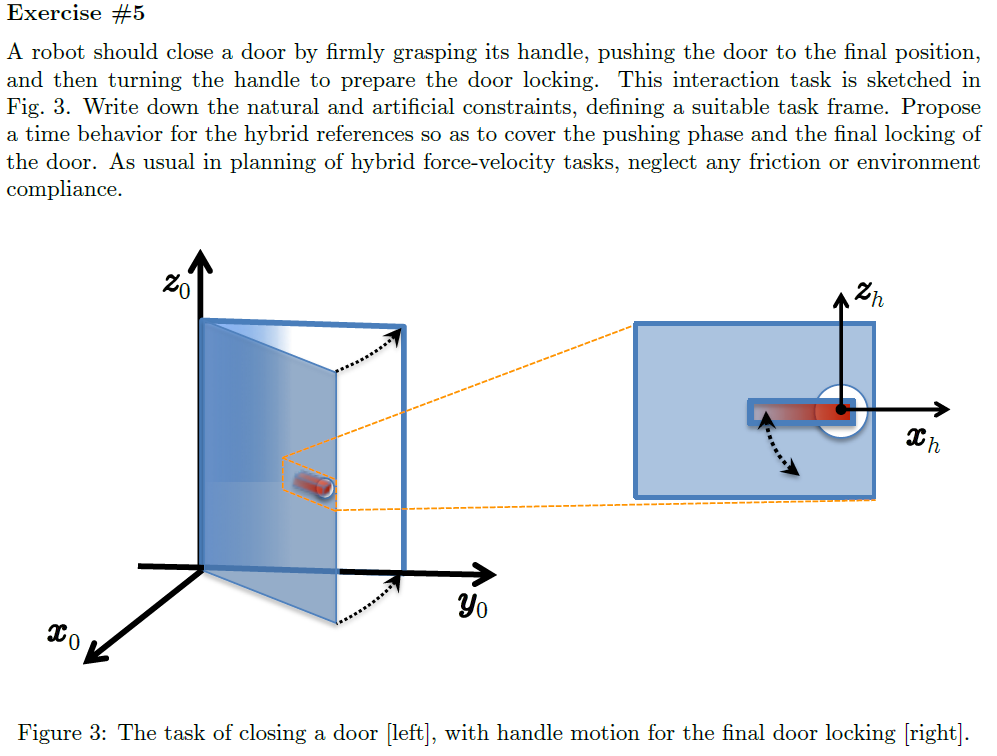

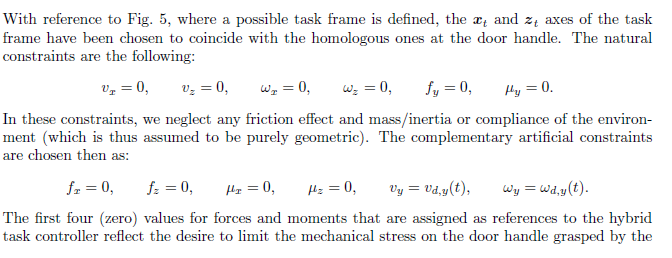

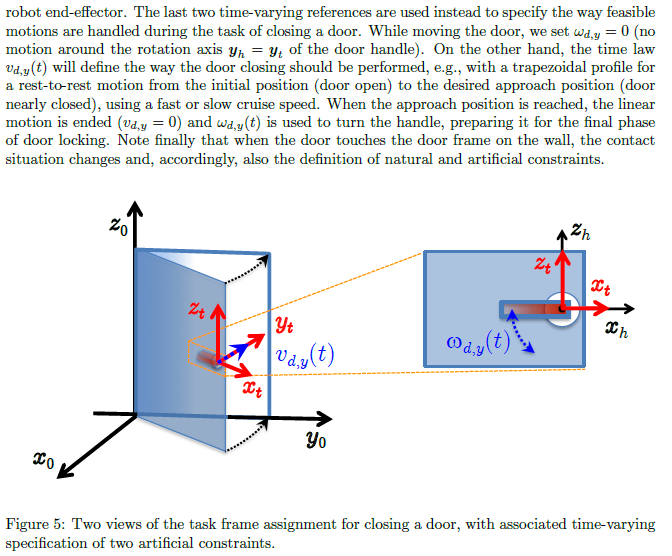

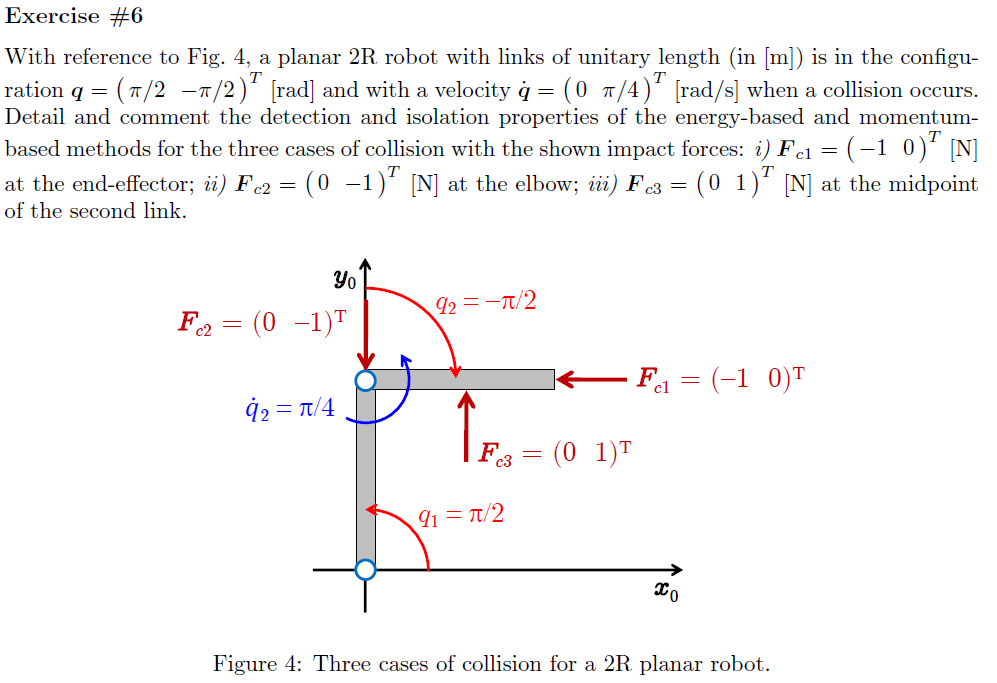

% % This part is isolated from previous section
% clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% m(2)=m(2)+m_p;
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real');
% g0 = sym('g0','real');
% g=[0,0,-g0]';
% R2Robot=['rr';'xx';sigma]    
% z = Gen_param(n);
% z.g=g;
% z.g0=g0;
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% z.l_=[1,1]';
% 
% % z.opt_expr={[l;dc],[z.l_;z.l_/2]};
% % z.rcdefined=true;

## defining collisions

% 
% % collide1=
% z.collides=[struct('F',[-1,0,0]' ,'joint',2,'F_pos',l(2)),
%             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
%             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(2)

## computing

% 
% % 
% %    
% % % xyonly=true
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % % VarShortRobot.M
% % % angle_desired=[0,0]
% z.q_=[pi/2,-pi/2]';
% z.q_dot_=[0,pi/4]';
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)
% zout.J_c_collisions{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% 
% zout.J_c_collisions_{:}
% zout.vc_collisions_
% zout.Vc_T_dot_Fk_
% zout.Tau_c_
% 
% (z.q_dot_'*zout.Tau_c_)'
% 
% vc_=subs(vc,q,z.q_)
% [C,cac,Csubs,S] = getCs(M,q,q_dot);